timestep = 6500; 
volumes = 200;
% lambda = 0.1
lambda = [ones(1, volumes/2), 2*ones(1, volumes/2)];

solver = DiffusionSolver( ...
    volumes, ...
    timestep, ...
    lambda);

% solver.setStartingCondition( @(x) abs(sin(5*x)) );
solver.setStartingCondition();
% solver.setStartingCondition(@(x) 0);

% solver.setDirichletBC(round(volumes/3), 5);
% solver.setDirichletBC(volumes, 5);

solver.setDirichletBC(1, 0);
solver.setDirichletBC(volumes, 0);

% solver.setSinglePointNeumannBC(68, 20, 1, 600);

solver.solve()

clf
hold on
ylabel('U')
xlabel('x')
solver.plot(1)
solver.plot(50)
solver.plot(200)
solver.plot(1000)
solver.plot(3000)
solver.plot(6000)
legend(strcat(...
    num2str(...
    [solver.currentTime(1);...
    solver.currentTime(50); ...
    solver.currentTime(200); ...
    solver.currentTime(1000); ...
    solver.currentTime(3000);  ...
    solver.currentTime(6000)], 1)...
    , 's'))
hold off

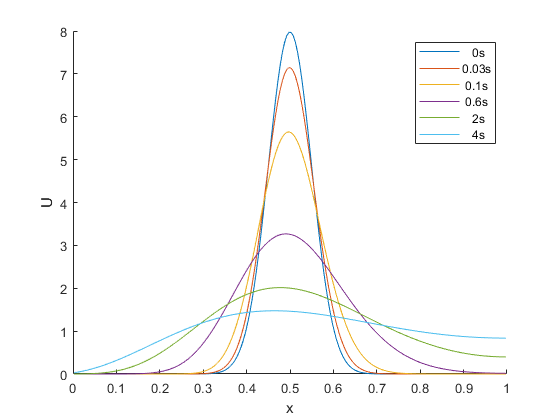

solver.plotAnimated(100)
solver.plot()
hold off
solver.plotIntegral()